# Industrial NP samples

## Importing the data

PMMA_data = xlsread('PMMA_samples.xlsx');
PUR1_data = xlsread('PUR_1_samples.xlsx');
PUR2_data = xlsread('PUR_2_samples.xlsx');

% UV_trend imported from 'HDC_deconvolution.mat'

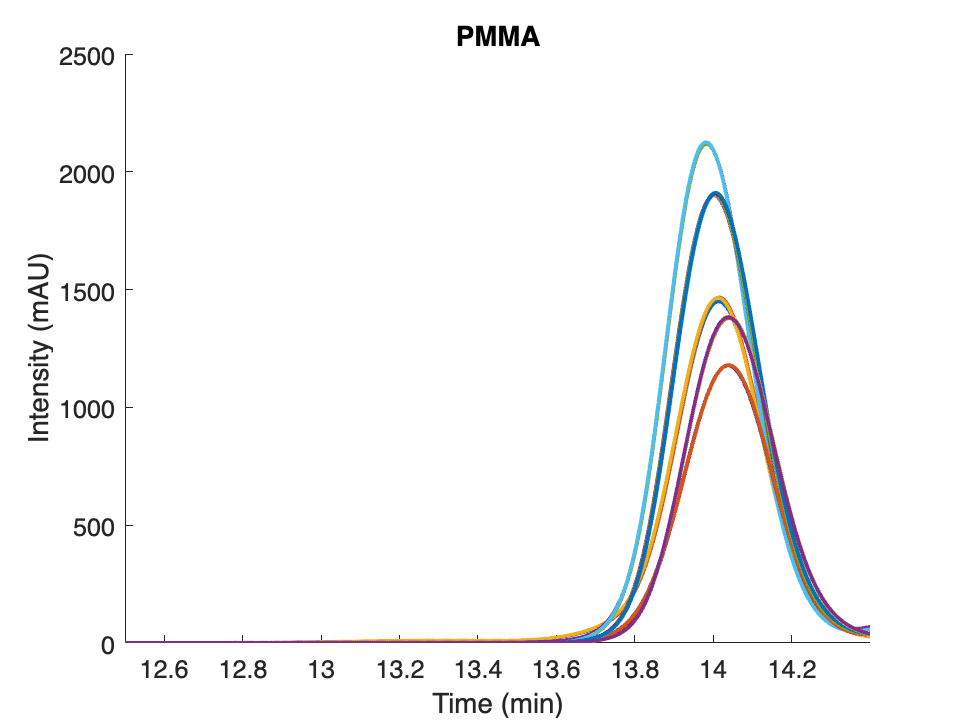

% Time chromatograms
time = PMMA_data(7201:end-1,1);

figure
hold on 
plot(time, PMMA_data(7201:end-1,2:end), 'LineWidth',2);
set(gca, 'FontSize', 14); 
ax = gca; 
xlabel('Time (min)'); ylabel('Intensity (mAU)'); 
xlim([12.5 14.4]);
ylim([0,2500]);
title('PMMA');
hold off

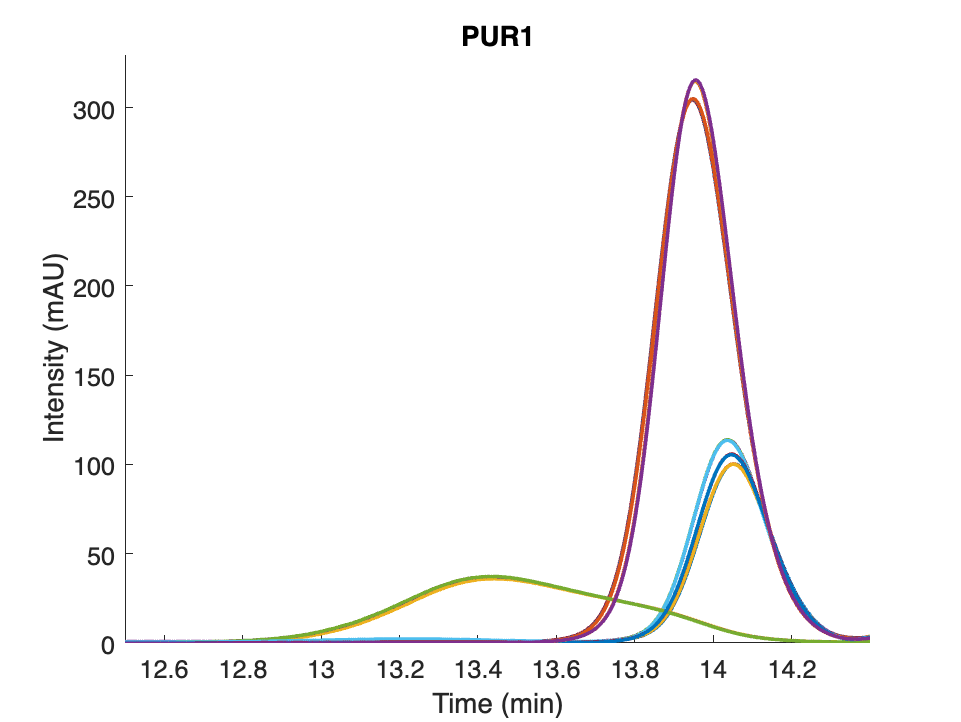


figure
hold on 
plot(time, PUR1_data(7201:end-1,2:end), 'LineWidth',2);
set(gca, 'FontSize', 14); 
ax = gca; 
xlabel('Time (min)'); ylabel('Intensity (mAU)'); 
xlim([12.5 14.4]);
ylim([0,330]);
title('PUR1');
hold off

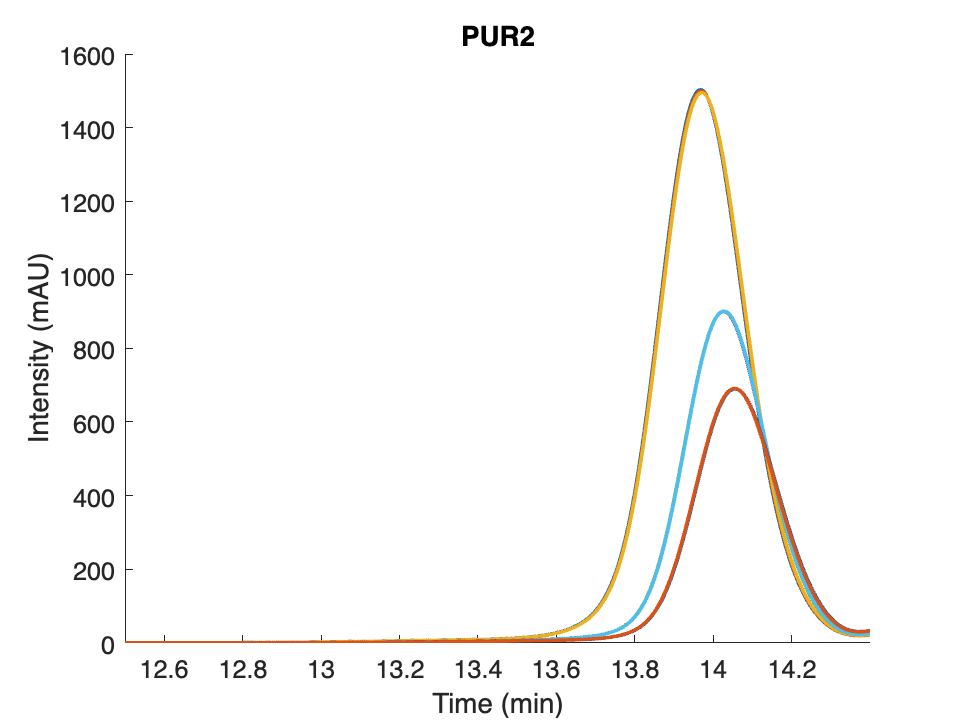


figure
hold on 
plot(time, PUR2_data(7201:end-1,2:end), 'LineWidth',2);
set(gca, 'FontSize', 14); 
ax = gca; 
xlabel('Time (min)'); ylabel('Intensity (mAU)'); 
xlim([12.5 14.4]);
ylim([0,1600]);
title('PUR2');
hold off

% Combine all chromatograms in one big matrix
NP_data = [PMMA_data(1:9000,2:end) PUR1_data(1:9000,2:end) PUR2_data(1:9000,2:end)];
time_full = PMMA_data(1:9000,1);

% Find peak height, position, width
NP_para = zeros(size(NP_data,2),3);

for i = 1:size(NP_data,2)
    [hgt, locs, wds] = findpeaks(NP_data(:,i),time_full,'MinPeakHeight',1, 'Annotate', 'extents', 'WidthReference', 'halfheight','SortStr','descend','NPeaks',1);
    NP_para(i,:) = [hgt(1) locs(1) wds(1)];
end
NP_sig = NP_para(:,3)./2.35;                    % peak width in sigma
var_app = NP_sig.^2;                            % apparant peak variance


% Determine remainder variance based on var_sys LOD
p_var_2 = [-0.0035254420770712163	0.09766187346707801	-0.6685676221175144]; % based on PS calibration
var_sys = polyval(p_var_2,NP_para(:,2));        % determine system variance of detected peaks (polynomial from simulated_HDC_chromatograms.mlx)
max_var = 0.0001042;                            % var LOD from Excel

var_rem_temp = var_app - var_sys;               % temporary var_res without considering LOD 
low_var_rem = var_rem_temp < max_var;           % LOD correction: var_res_temp = max_STD_var if var_res_temp < max_STD_var
var_rem = zeros(length(var_rem_temp),1);
for i = 1:length(var_rem_temp)
    if low_var_rem(i,:) == 1
        var_rem(i,:) = max_STD_var;             % LOD of observable variance
    else
        var_rem(i,:) = var_rem_temp(i,:);       % above LOD of observable variance
    end
end
sig_rem = sqrt(var_rem);

% Combine all peak parameters
NP_overview = [NP_para, NP_sig, var_app, var_sys, var_rem_temp, var_rem, sig_rem];

% PSD-extracted chromatograms (time)
NP_app_n = NP_data./max(NP_data);               % normalized chromatograms
NP_rem = zeros(length(time),length(NP_overview));
rem_t_para = zeros(length(NP_overview),3);
for i = 1:size(NP_app_n(7201:end,:),2)
    NP_rem(:,i) = gauss(time, 1, NP_overview(i,2),NP_overview(i,9))./max(gauss(time, 1, NP_overview(i,2),NP_overview(i,9)));
end

for j = 1:size(NP_rem,2)
    [hgt, locs, wds] = findpeaks(NP_rem(:,j),time,'MinPeakHeight',0.1, 'Annotate', 'extents', 'WidthReference', 'halfheight','SortStr','descend','NPeaks',1);
    rem_t_para(j,:) = [hgt(1) locs(1) wds(1)];
end
sig_rem = rem_t_para(:,3)./2.35;
var_rem = sig_rem.^2;

rem_t_overview = [rem_t_para, sig_rem, var_rem];    % overview remainder peak parameters in time dimension
NP_rem_size = [x_size,NP_rem]; % Make a matrix with all size info
[x_unique, idx_unique, uniques] = unique(x_size(1:1349),'first'); % prepare increasing size axis without duplicates

# Application industrial NPs

## PMMA

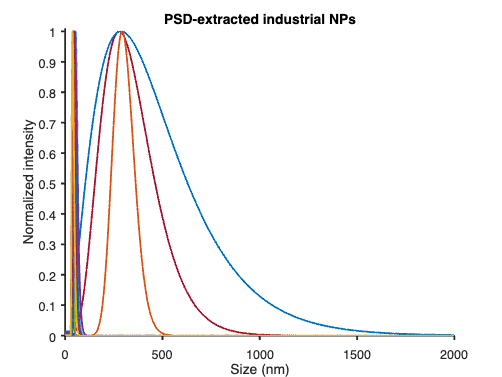

% % Prepare PSD-extracted chromatograms (size)
% figure
% hold on
% plot(x_size,NP_rem,'LineWidth',2); 
% set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
% ax = gca;
% xlabel('Size (nm)'); ylabel('Normalized intensity'); 
% title('PSD-extracted industrial NPs');
% xlim([0 2000]);
% ylim([0 1.01]);
% hold off

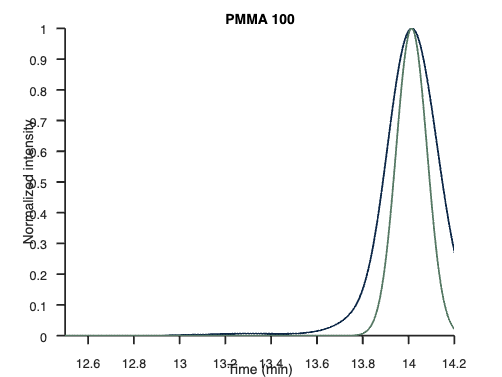

% PMMA 100
% i = 2;
% j = 1; 
% figure
% hold on
% plot(time,PMMA_data(7201:end-1,i)./max(PMMA_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
% ax = gca;
% xlabel('Time (min)'); ylabel('Normalized intensity'); 
% title('PMMA 100');
% xlim([12.5 14.2]);
% ylim([0 1]);
% hold off

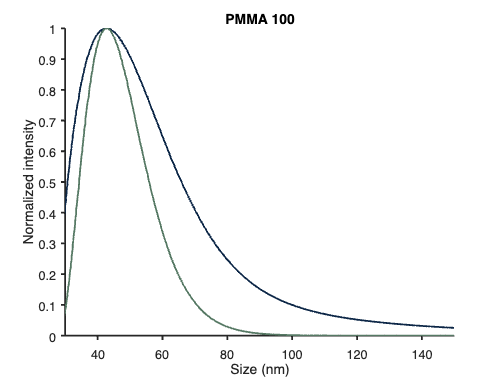

% 
% figure
% hold on
% plot(x_size,PMMA_data(7201:end-1,i)./max(PMMA_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(x_size,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
% ax = gca;
% xlabel('Size (nm)'); ylabel('Normalized intensity'); 
% title('PMMA 100');
% xlim([30 150]);
% ylim([0 1]);
% hold off

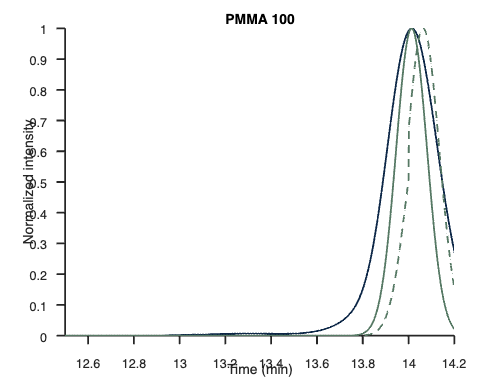

% UV correction
% i = 2;
% j = 1;
% NP_rem_UV = NP_rem(:,j).*(1./UV_trend(:,2)); NP_rem_UV_n = NP_rem_UV./max(NP_rem_UV);
% figure
% hold on
% plot(time,PMMA_data(7201:end-1,i)./max(PMMA_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964');
% plot(time,NP_rem_UV_n(:,j),'LineWidth',2,'color', '#567964','LineStyle','--');
% set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
% ax = gca;
% xlabel('Time (min)'); ylabel('Normalized intensity');
% title('PMMA 100');
% xlim([12.5 14.2]);
% ylim([0 1]);
% hold off

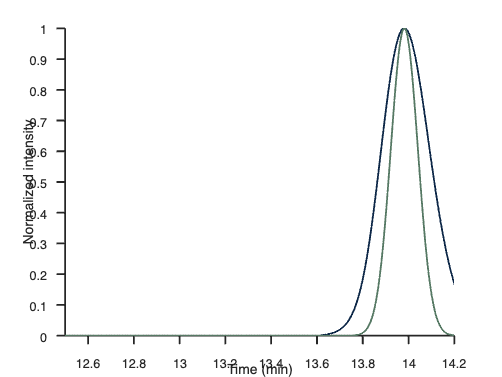

%%% PMMA 90
i = 7;
j = 6; 
figure
hold on
plot(time,PMMA_data(7201:end-1,i)./max(PMMA_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
%title('PMMA 90');
xlim([12.5 14.2]);
ylim([0 1]);
hold off

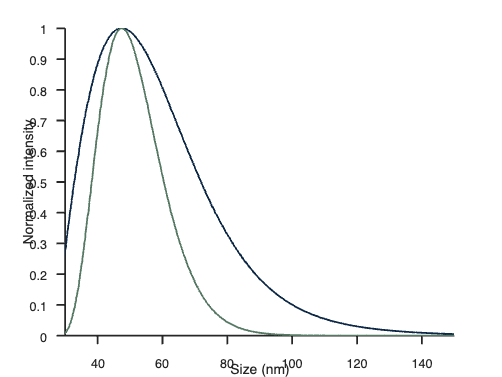


figure
hold on
plot(x_size,PMMA_data(7201:end-1,i)./max(PMMA_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
plot(x_size,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
%title('PMMA 90');
xlim([30 150]);
ylim([0 1]);
hold off


[x_unique, idx_unique, uniques] = unique(x_size(1:1349),'first'); 
pop_u = NP_rem(idx_unique,j);
[hgts, locs, wds] = findpeaks(pop_u, x_unique(:,1), 'MinPeakHeight',0.8,'Annotate','extents');
p_sigma = [wds/2.35];
p_var = p_sigma.^2;
pmma_90 = [locs; p_sigma; p_var]';

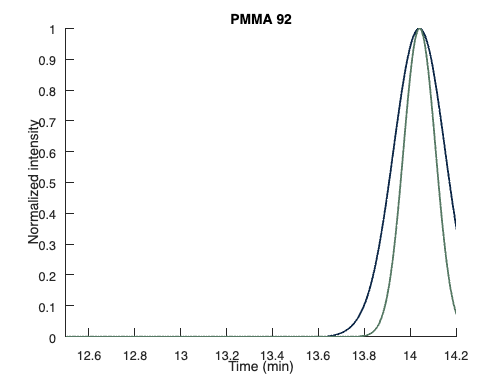

% % PMMA 92
% i = 10;
% j = 9; 
% figure
% hold on
% plot(time,PMMA_data(7201:end-1,i)./max(PMMA_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Time (min)'); ylabel('Normalized intensity'); 
% title('PMMA 92');
% xlim([12.5 14.2]);
% ylim([0 1]);
% hold off

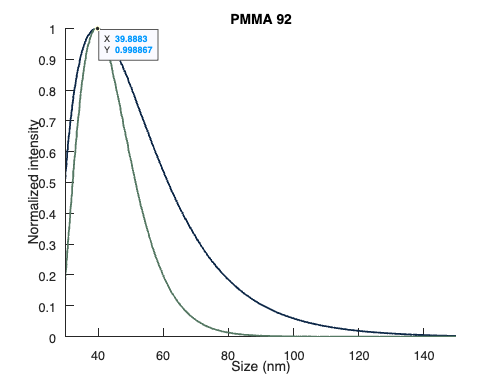

% 
% figure
% hold on
% plot(x_size,PMMA_data(7201:end-1,i)./max(PMMA_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(x_size,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Size (nm)'); ylabel('Normalized intensity'); 
% title('PMMA 92');
% xlim([30 150]);
% ylim([0 1]);
% hold off

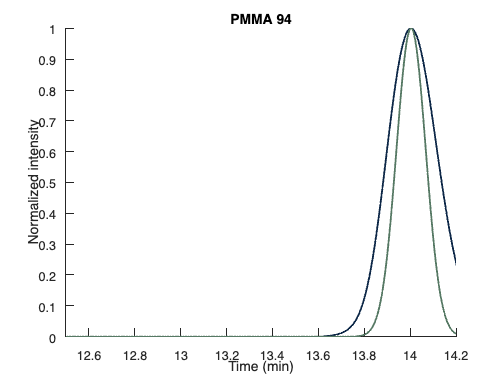

% % PMMA 94
% figure
% hold on
% plot(time,PMMA_data(7201:end-1,13)./max(PMMA_data(7201:end-1,13)),'LineWidth',2,'color', '#0D2747')
% plot(time,NP_rem(:,12),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Time (min)'); ylabel('Normalized intensity'); 
% title('PMMA 94');
% xlim([12.5 14.2]);
% ylim([0 1]);
% hold off

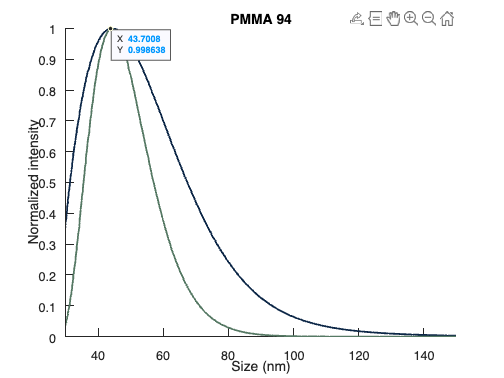

% 
% figure
% hold on
% plot(x_size,PMMA_data(7201:end-1,13)./max(PMMA_data(7201:end-1,13)),'LineWidth',2,'color', '#0D2747')
% plot(x_size,NP_rem(:,12),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Size (nm)'); ylabel('Normalized intensity'); 
% title('PMMA 94');
% xlim([30 150]);
% ylim([0 1]);
% hold off

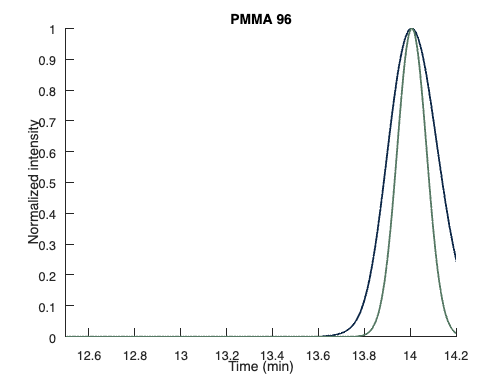

% % PMMA 96
% figure
% hold on
% plot(time,PMMA_data(7201:end-1,16)./max(PMMA_data(7201:end-1,16)),'LineWidth',2,'color', '#0D2747')
% plot(time,NP_rem(:,15),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Time (min)'); ylabel('Normalized intensity'); 
% title('PMMA 96');
% xlim([12.5 14.2]);
% ylim([0 1]);
% hold off

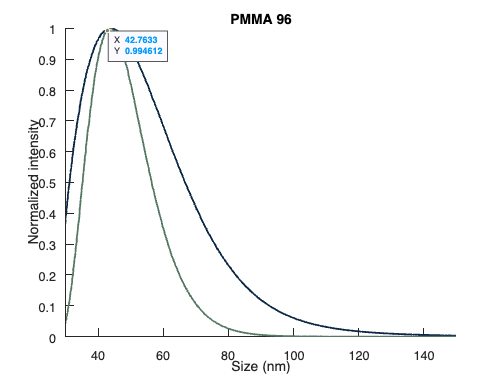

% 
% figure
% hold on
% plot(x_size,PMMA_data(7201:end-1,16)./max(PMMA_data(7201:end-1,16)),'LineWidth',2,'color', '#0D2747')
% plot(x_size,NP_rem(:,15),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Size (nm)'); ylabel('Normalized intensity'); 
% title('PMMA 96');
% xlim([30 150]);
% ylim([0 1]);
% hold off

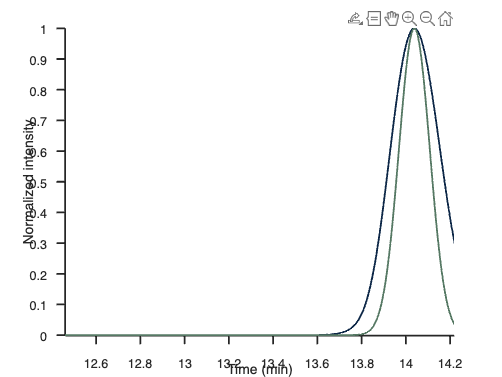

% PMMA 98
i = 19;
j = 18; 
figure
hold on
plot(time,PMMA_data(7201:end-1,i)./max(PMMA_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
%title('PMMA 98');
xlim([12.5 14.2]);
ylim([0 1]);
hold off

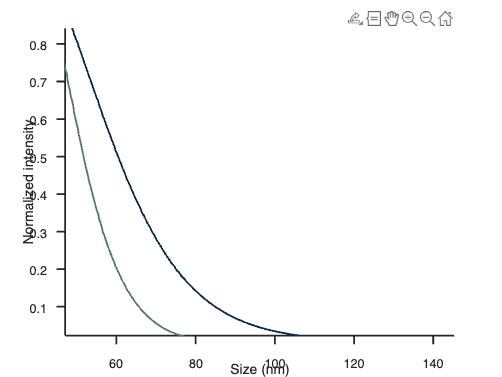


figure
hold on
plot(x_size,PMMA_data(7201:end-1,i)./max(PMMA_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
plot(x_size,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
%title('PMMA 98');
xlim([30 150]);
ylim([0 1]);
hold off


[x_unique, idx_unique, uniques] = unique(x_size(1:1349),'first'); 
pop_u = NP_rem(idx_unique,j);
[hgts, locs, wds] = findpeaks(pop_u, x_unique(:,1), 'MinPeakHeight',0.8,'Annotate','extents');
p_sigma = [wds/2.35];
p_var = p_sigma.^2;
pmma_98 = [locs; p_sigma; p_var]';

## PUR (A)

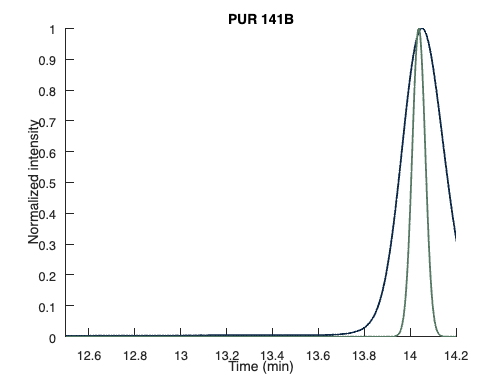

% % PUR 141B 
% i = 4;
% j = 22; 
% figure
% hold on
% plot(time,PUR1_data(7201:end-1,i)./max(PUR1_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Time (min)'); ylabel('Normalized intensity'); 
% title('PUR 141B');
% xlim([12.5 14.2]);
% ylim([0 1]);
% hold off

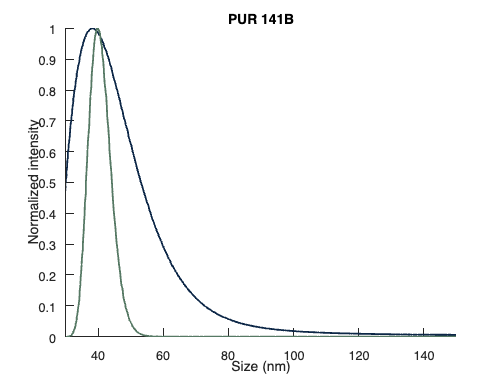

% 
% figure
% hold on
% plot(x_size,PUR1_data(7201:end-1,i)./max(PUR1_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(x_size,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Size (nm)'); ylabel('Normalized intensity'); 
% title('PUR 141B');
% xlim([30 150]);
% ylim([0 1]);
% hold off

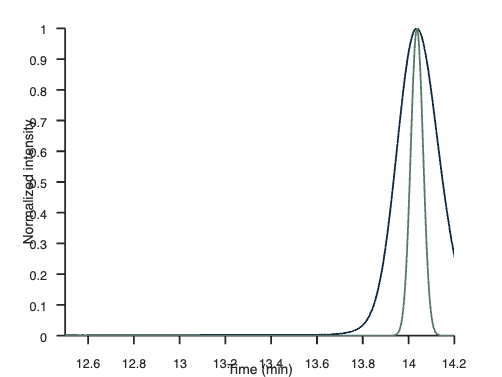

% PUR 161
i = 6;
j = 24; 
figure
hold on
plot(time,PUR1_data(7201:end-1,i)./max(PUR1_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
%title('PUR 161');
xlim([12.5 14.2]);
ylim([0 1]);
hold off

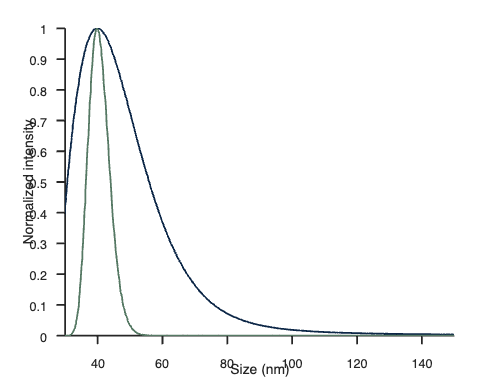


figure
hold on
plot(x_size,PUR1_data(7201:end-1,i)./max(PUR1_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
plot(x_size,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
%title('PUR 161');
xlim([30 150]);
ylim([0 1]);
hold off


pop_u = NP_rem(idx_unique,j);
[hgts, locs, wds] = findpeaks(pop_u, x_unique(:,1), 'MinPeakHeight',0.8,'Annotate','extents');
p_sigma = [wds/2.35];
p_var = p_sigma.^2;
pur_161 = [locs; p_sigma; p_var]';

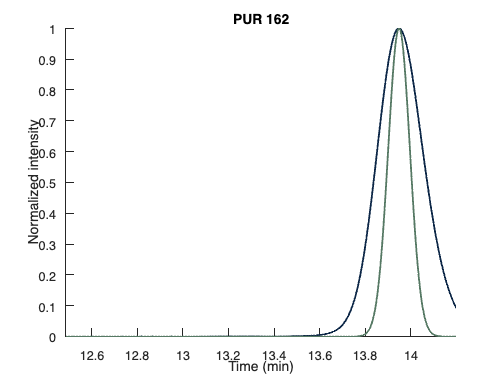

% % PUR 162
% i = 9;
% j = 27; 
% figure
% hold on
% plot(time,PUR1_data(7201:end-1,i)./max(PUR1_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Time (min)'); ylabel('Normalized intensity'); 
% title('PUR 162');
% xlim([12.5 14.2]);
% ylim([0 1]);
% hold off

% 
% figure
% hold on
% plot(x_size,PUR1_data(7201:end-1,i)./max(PUR1_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(x_size,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Size (nm)'); ylabel('Normalized intensity'); 
% title('PUR 162');
% xlim([30 150]);
% ylim([0 1]);
% hold off

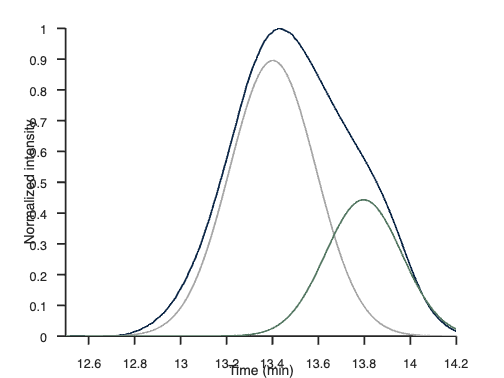

% PUR 165-2 
i = 12;
j = 30; 
figure
hold on
chrom = PUR1_data(7201:end-1,i) - 0.672437;
chrom_n = chrom./max(chrom);
% deconvolution gausseqv n=2
pop_1 = gauss(time,0.8958,13.4017,0.188307435); pop_1_n = (pop_1./max(pop_1))*0.89532;
pop_2 = gauss(time,0.4435,13.7967,0.165963851); pop_2_n = (pop_2./max(pop_2))*0.442894;
plot(time,chrom_n,'LineWidth',2,'color', '#0D2747')
plot(time,pop_1_n,'LineWidth',2,'color', '#A7A7A7')
plot(time,pop_2_n,'LineWidth',2,'color', '#567964')
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
xlim([12.5 14.2]);
ylim([0 1]);
hold off

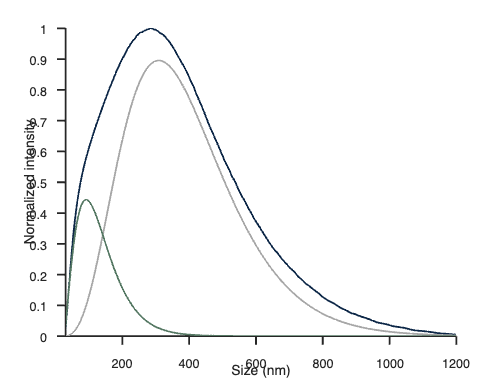


figure
hold on
plot(x_size,chrom_n,'LineWidth',2,'color', '#0D2747')
plot(x_size,pop_1_n,'LineWidth',2,'color', '#A7A7A7'); 
plot(x_size,pop_2_n,'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
xlim([30 1200]);
ylim([0 1]);
hold off


[x_unique, idx_unique, uniques] = unique(x_size(1:1349),'first'); 
pop_1_u = pop_1_n(idx_unique); % population 1
[hgts1, locs1, wds1] = findpeaks(pop_1_u, x_unique(:,1), 'MinPeakHeight',0.8,'Annotate','extents');
p1_sigma = [wds1/2.35];
p1_var = p1_sigma.^2;
p1_1652 = [locs1; p1_sigma; p1_var]';

pop_2_u = pop_2_n(idx_unique); % population 2
[hgts2, locs2, wds2] = findpeaks(pop_2_u, x_unique(:,1), 'MinPeakHeight',0.3,'Annotate','extents');
p2_sigma = [wds2/2.35];
p2_var = p2_sigma.^2;
p2_1652 = [locs2; p2_sigma; p2_var]';

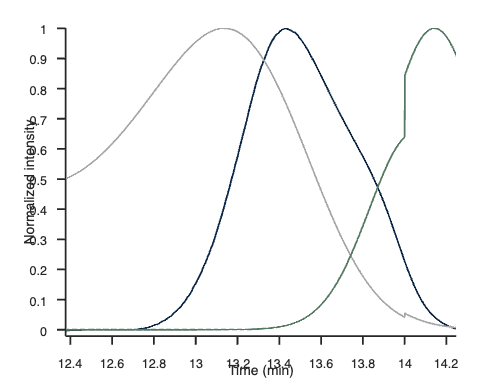

% PUR 165-2 >>> With UV cor
i = 12;
j = 30; 
figure
hold on
chrom = PUR1_data(7201:end-1,i) - 0.672437;
chrom_n = chrom./max(chrom);
% deconvolution gausseqv n=2
pop_1 = gauss(time,0.8958,13.4017,0.188307435); pop_1_n = (pop_1./max(pop_1))*0.89532;
pop_2 = gauss(time,0.4435,13.7967,0.165963851); pop_2_n = (pop_2./max(pop_2))*0.442894;
pop_1_UV = pop_1_n.*(1./UV_trend(:,2)); pop_1_UV_n = pop_1_UV./max(pop_1_UV);
pop_2_UV = pop_2_n.*(1./UV_trend(:,2)); pop_2_UV_n = pop_2_UV./max(pop_2_UV);
plot(time,chrom_n,'LineWidth',2,'color', '#0D2747')
plot(time,pop_1_UV_n,'LineWidth',2,'color', '#A7A7A7')
plot(time,pop_2_UV_n,'LineWidth',2,'color', '#567964')
%NP_rem_UV = NP_rem(:,j).*(1./UV_trend(:,2)); NP_rem_UV_n = NP_rem_UV./max(NP_rem_UV);
%plot(time,NP_rem_UV_n,'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
%title('PUR 165-2');
xlim([12.5 14.2]);
ylim([0 1]);
hold off


% figure
% hold on
% plot(time,PUR1_data(7201:end-1,i)./max(PUR1_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Time (min)'); ylabel('Normalized intensity'); 
% title('PUR 161');
% xlim([12.5 14.2]);
% ylim([0 1]);
% hold off
% 
% figure
% hold on
% plot(x_size,PUR1_data(7201:end-1,i)./max(PUR1_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(x_size,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Size (nm)'); ylabel('Normalized intensity'); 
% title('PUR 161');
% xlim([30 150]);
% ylim([0 1]);
% hold off

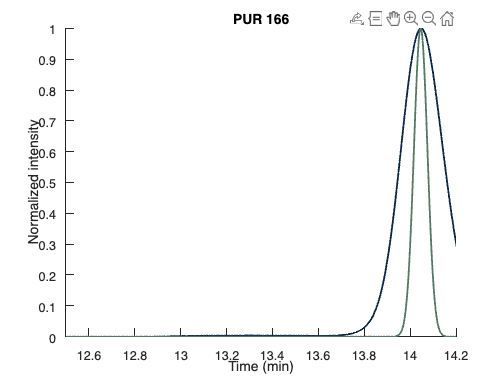

% % PUR 166
% i = 15;
% j = 33; 
% figure
% hold on
% plot(time,PUR1_data(7201:end-1,i)./max(PUR1_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Time (min)'); ylabel('Normalized intensity'); 
% title('PUR 166');
% xlim([12.5 14.2]);
% ylim([0 1]);
% hold off

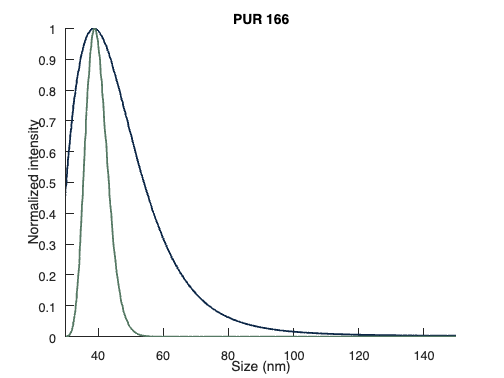

% 
% figure
% hold on
% plot(x_size,PUR1_data(7201:end-1,i)./max(PUR1_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(x_size,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Size (nm)'); ylabel('Normalized intensity'); 
% title('PUR 166');
% xlim([30 150]);
% ylim([0 1]);
% hold off

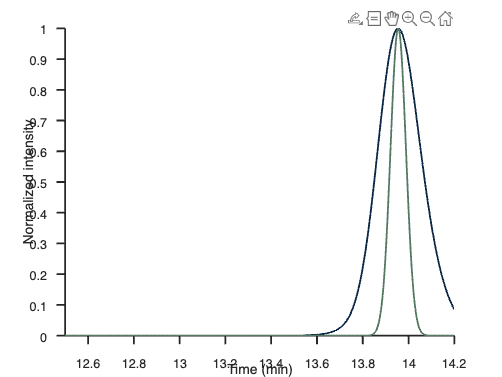

% PUR 167
i = 18;
j = 36; 
figure
hold on
plot(time,PUR1_data(7201:end-1,i)./max(PUR1_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
%title('PUR 167');
xlim([12.5 14.2]);
ylim([0 1]);
hold off

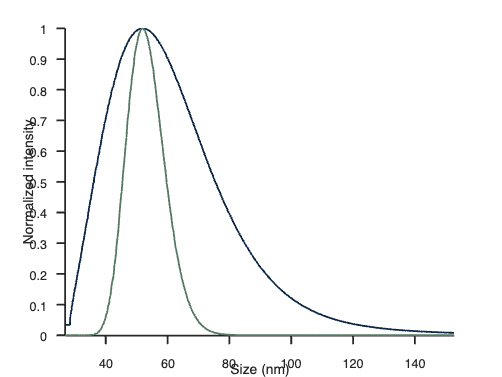


figure
hold on
plot(x_size,PUR1_data(7201:end-1,i)./max(PUR1_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
plot(x_size,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
%title('PUR 167');
xlim([30 150]);
ylim([0 1]);
hold off


pop_u = NP_rem(idx_unique,j);
[hgts, locs, wds] = findpeaks(pop_u, x_unique(:,1), 'MinPeakHeight',0.8,'Annotate','extents');
p_sigma = [wds/2.35];
p_var = p_sigma.^2;
pur_167 = [locs; p_sigma; p_var]';

## PUR (C)

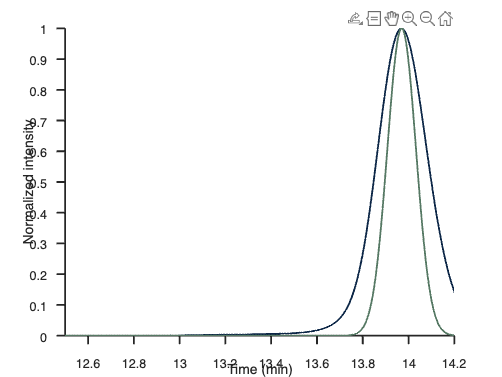

% PUR 4
i = 3;
j = 39; 
figure
hold on
plot(time,PUR2_data(7201:end-1,i)./max(PUR2_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
%title('PUR 4');
xlim([12.5 14.2]);
ylim([0 1]);
hold off

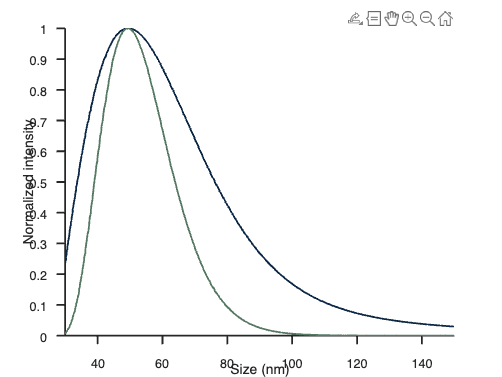


figure
hold on
plot(x_size,PUR2_data(7201:end-1,i)./max(PUR2_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
plot(x_size,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
%title('PUR 4');
xlim([30 150]);
ylim([0 1]);
hold off


pop_u = NP_rem(idx_unique,j);
[hgts, locs, wds] = findpeaks(pop_u, x_unique(:,1), 'MinPeakHeight',0.8,'Annotate','extents');
p_sigma = [wds/2.35];
p_var = p_sigma.^2;
pur_4 = [locs; p_sigma; p_var]';

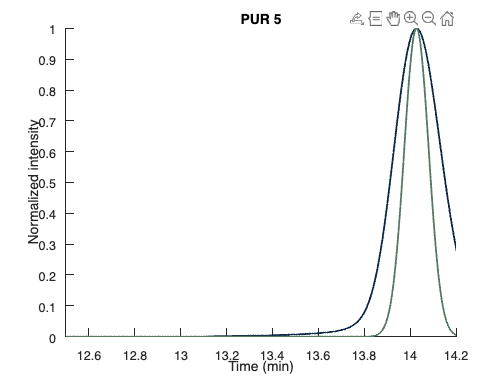

% % PUR 5
% i = 6;
% j = 42; 
% figure
% hold on
% plot(time,PUR2_data(7201:end-1,i)./max(PUR2_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Time (min)'); ylabel('Normalized intensity'); 
% title('PUR 5');
% xlim([12.5 14.2]);
% ylim([0 1]);
% hold off

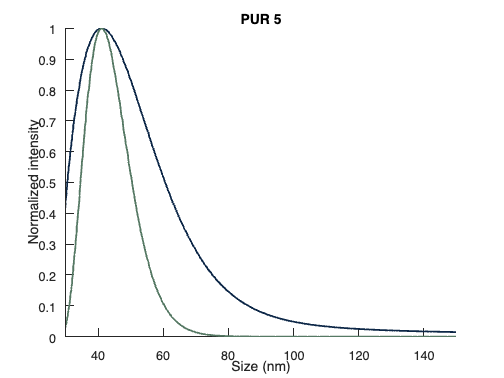

% 
% figure
% hold on
% plot(x_size,PUR2_data(7201:end-1,i)./max(PUR2_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
% plot(x_size,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Size (nm)'); ylabel('Normalized intensity'); 
% title('PUR 5');
% xlim([30 150]);
% ylim([0 1]);
% hold off

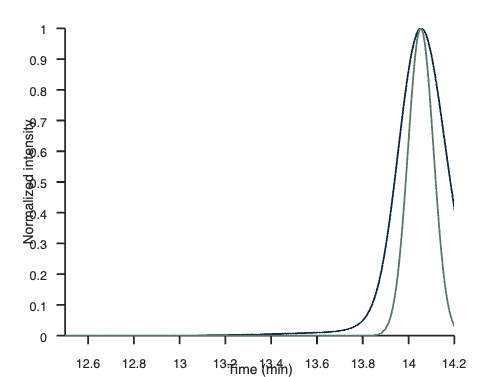

% PUR 6
i = 9;
j = 45; 
figure
hold on
plot(time,PUR2_data(7201:end-1,i)./max(PUR2_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
plot(time,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
%title('PUR 6');
xlim([12.5 14.2]);
ylim([0 1]);
hold off

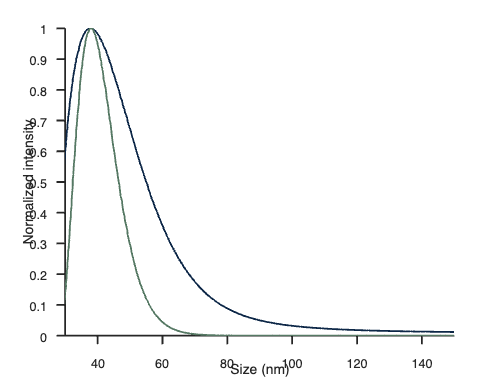


figure
hold on
plot(x_size,PUR2_data(7201:end-1,i)./max(PUR2_data(7201:end-1,i)),'LineWidth',2,'color', '#0D2747')
plot(x_size,NP_rem(:,j),'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
%title('PUR 6');
xlim([30 150]);
ylim([0 1]);
hold off


pop_u = NP_rem(idx_unique,j);
[hgts, locs, wds] = findpeaks(pop_u, x_unique(:,1), 'MinPeakHeight',0.8,'Annotate','extents');
p_sigma = [wds/2.35];
p_var = p_sigma.^2;
pur_6 = [locs; p_sigma; p_var]';



# New attempt UV correction PUR exoot

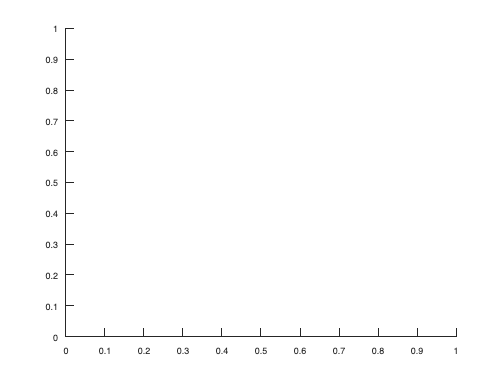

% PUR 165-2 
i = 12;
j = 30; 
figure
hold on

chrom = PUR1_data(7201:end-1,i) - 0.672437;
chrom_n = chrom./max(chrom);

% deconvolution gausseqv n=2
pop_1 = gauss(time,0.8958,13.4017,0.188307435); pop_1_n = (pop_1./max(pop_1))*0.89532;
pop_2 = gauss(time,0.4435,13.7967,0.165963851); pop_2_n = (pop_2./max(pop_2))*0.442894;

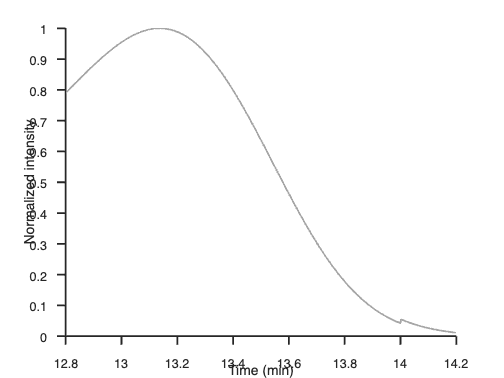

pop_1_norm = pop_1./max(pop_1);
pop_1_UV = pop_1_norm.*(1./UV_trend(:,2)); pop_1_UV_n = pop_1_UV./max(pop_1_UV);
figure;
hold on
plot(time,pop_1_UV_n,'LineWidth',2,'color', '#A7A7A7')
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
xlim([12.8 14.2]);
ylim([0 1]);
hold off

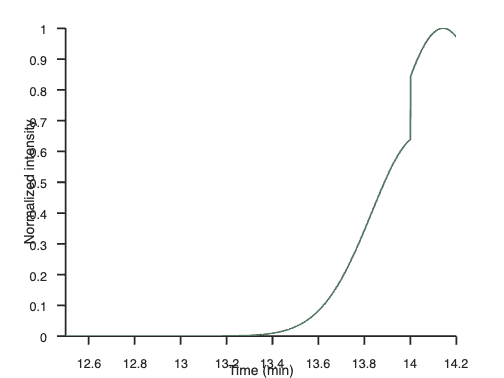

pop_2_norm = pop_2./max(pop_2);
pop_2_UV = pop_2_norm.*(1./UV_trend(:,2)); pop_2_UV_n = pop_2_UV./max(pop_2_UV);
figure;
hold on
plot(time,pop_2_UV_n,'LineWidth',2,'color', '#567964')
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
xlim([12.5 14.2]);
ylim([0 1]);
hold off


% pop_1_UV = pop_1_n.*(1./UV_trend(:,2)); pop_1_UV_n = pop_1_UV./max(pop_1_UV);
pop_2_UV = pop_2_n.*(1./UV_trend(:,2)); pop_2_UV_n = pop_2_UV./max(pop_2_UV);


plot(time,chrom_n,'LineWidth',2,'color', '#0D2747')
plot(time,pop_1_n,'LineWidth',2,'color', '#A7A7A7')
plot(time,pop_2_n,'LineWidth',2,'color', '#567964')
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
xlim([12.5 14.2]);
ylim([0 1]);
hold off

figure
hold on
plot(x_size,chrom_n,'LineWidth',2,'color', '#0D2747')
plot(x_size,pop_1_n,'LineWidth',2,'color', '#A7A7A7'); 
plot(x_size,pop_2_n,'LineWidth',2,'color', '#567964'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
ax = gca;
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
xlim([30 1200]);
ylim([0 1]);
hold off

[x_unique, idx_unique, uniques] = unique(x_size(1:1349),'first'); 
pop_1_u = pop_1_n(idx_unique); % population 1
[hgts1, locs1, wds1] = findpeaks(pop_1_u, x_unique(:,1), 'MinPeakHeight',0.8,'Annotate','extents');
p1_sigma = [wds1/2.35];
p1_var = p1_sigma.^2;
p1_1652 = [locs1; p1_sigma; p1_var]';

pop_2_u = pop_2_n(idx_unique); % population 2
[hgts2, locs2, wds2] = findpeaks(pop_2_u, x_unique(:,1), 'MinPeakHeight',0.3,'Annotate','extents');
p2_sigma = [wds2/2.35];
p2_var = p2_sigma.^2;
p2_1652 = [locs2; p2_sigma; p2_var]';

# Draft stuff below


[x_unique, idx_unique, uniques] = unique(x_size(1:1349),'rows');    % determine unique size values, without duplicates
for i = 1:length(idx_unique)
    for j = idx_unique(i)
        x_unique(i) = x_size(j);
        rem_size(i,:) = NP_rem(j,:);
    end
end

for k = 1:size(rem_size,2)
    [hgt, locs, wds] = findpeaks(rem_size(:,k),x_unique,'MinPeakHeight',0.1, 'Annotate', 'extents', 'WidthReference', 'halfheight','SortStr','descend','NPeaks',1);
    rem_s_para(k,:) = [hgt(1) locs(1) wds(1)];
end

Error using findpeaks
input vectors X and Y should have the same size.

rem_s_sig = rem_s_para(:,3)./2.45;
rem_s_var = rem_s_sig.^2;


% Calculate size peak parameters
[x_unique, idx_unique, uniques] = unique(x_size(1:1349),'rows');    % determine unique size values, without duplicates

for i = 1:length(idx_unique)
    for j = idx_unique(i)
        x_unique(i) = x_size(j);        % size values without duplicates, needed for findpeaks
        p1_525(i) = cor_t1_n(j,:);      % population 1
        p2_525(i) = cor_t2_n(j,:);      % population 2
        p3_525(i) = cor_t3_n(j,:);      % population 3
    end
end

populations = [p1_525; p2_525; p3_525]';
for k = 1:size(populations,2)
    [hgts(k) locs(k) wds(k)] = findpeaks(populations(:,k), x_unique(:,1),'MinPeakHeight',0.9);
end

sigma = [wds./2.35];
var = sigma.^2;
p_525 = [locs; sigma; var]';

% Categorize the NP samples by its indices
PMMA_100 = [1 2 3];
PMMA_90 = [4 5 6];
PMMA_92 = [7 8 9];
PMMA_94 = [10 11 12];
PMMA_96 = [13 14 15];
PMMA_98 = [16 17 18];
PUR_141B = [19 20 21];
PUR_161 = [22 23 24];
PUR_162 = [25 26 27];
PUR_165_2 = [28 29 30];
PUR_166 = [31 32 33];
PUR_167 = [34 35 36];
PUR_4 = [37 38 39];
PUR_5 = [40 41 42];
PUR_6 = [43 44 45];

for i = 1:length(PS_samples)
    for j = PS_samples(i)
        for k = PS_cor(i)
            figure
            hold on
            plot(time,PSData{j,1}(1:9000,2)./max(PSData{j,1}(1:9000,2)),'LineWidth',2,'color', colors_list{1}); % measured chrom
            title(PS_title{i});
            plot(time_x,cert_chrom_sn(:,i),'LineWidth',2,'color','#D06D91') % certified chrom
            cor_t = gauss(time,NP_BB_PS(k,2),NP_BB_PS(k,3),sig_res(k));
            cor_t_matrix(:,i) = gauss(time,NP_BB_PS(k,2),NP_BB_PS(k,3),sig_res(k));
            plot(time,cor_t./max(cor_t), 'LineWidth',2,'color', colors_list{5}) % corrected chrom
            set(gca, 'FontSize', 14); 
            ax = gca;
            xlabel('Time (min)'); ylabel('Normalized intensity'); 
            xlim([12.5 14.2]);
            ylim([0 1.01]);
            hold off
            [hgt, locs, wds] = findpeaks(cor_t,time,'MinPeakHeight',1, 'Annotate', 'extents', 'WidthReference', 'halfheight','SortStr','descend');
            PScor_t_sigma(:,i) = wds/2.35;
        end
    end
end